## Valores del circuito


$$\matrix{
\text{ }		& \text{Buck} 	& \text{Boost}	\cr
Vi				& 30V 			& 5V			\cr
D				& {}^1/_6          	&{}^1/_2           	\cr
f				& 31250Hz 		& 31250Hz		\cr
L				& 68\mu H 		& 22\mu H		\cr
C				& 100\mu F 		& 100\mu F		\cr
}$$


## Cargas


$$\matrix{
R_L				& \text{Buck} 	& \text{Boost}	\cr
CCM				& 2\Omega		& 8\Omega		\cr
DCM				& 10\Omega		& 20\Omega		\cr
\text{Limite}	& 5\Omega		& 10\Omega		\cr
}$$


clear all

%Buck
%modo = 'Buck-CCM';
%modo = 'Buck-Caso limite';
%modo = 'Buck-DCM';

%Boost
%modo = 'Boost-CCM';
%modo = 'Boost-Caso limite';
modo = 'Boost-DCM';

circuito='boost';
estado='DCM';

Rl=20;

Vi=5;
D=1/2;
f=31250;
L=22e-6;
C=100e-6;

T=1/f;

## Simulink

Ejecutamos el modelo de simulink

tstop=223*T;
stepsize=T/1000;
out=sim('circuito_boost.slx','StopTime','tstop','FixedStep','stepsize')

out =   Simulink.SimulationOutput:

                    i_c: [223001x1 double] 
                    i_d: [223001x1 double] 
                   i_in: [223001x1 double] 
                    i_l: [223001x1 double] 
                  i_out: [223001x1 double] 
                      t: [223001x1 double] 
                   tout: [223001x1 double] 
                    v_c: [223001x1 double] 
                    v_d: [223001x1 double] 
                   v_in: [223001x1 double] 
                    v_l: [223001x1 double] 
                  v_out: [223001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


%out=sim('circuito_buck.slx','StopTime','tstop','FixedStep','stepsize')

## Graficas

Ahora generamos las graficas

inicio=220*T;
final=223*T;

tiledlayout(8,1)

situacion=[sprintf(' [%s R=%0.1f',modo,Rl) ' \Omega]'];
nombre=strcat(modo, '-graficas');
ejex='t[s]';
sizetext=8;

% Tensió salida
ax1 = nexttile;
titulo='Tensión salida';
ejey='Vout[V]';
titulo=[titulo situacion];
TFGPlot(ax1,out.t,out.v_out,inicio,final,titulo,ejex,ejey,sizetext);

% Corriente salida
ax2 = nexttile;
titulo='Corriente salida';
ejey='iout[V]';
titulo=[titulo situacion];
TFGPlot(ax2,out.t,out.i_out,inicio,final,titulo,ejex,ejey,sizetext);

% Tensió bobina
ax3 = nexttile;
titulo='Tensión bobina';
ejey='Vl[V]';
titulo=[titulo situacion];
TFGPlot(ax3,out.t,out.v_l,inicio,final,titulo,ejex,ejey,sizetext);

% Corriente bobina
ax4 = nexttile;
titulo='Corriente bobina';
ejey='il[A]';
titulo=[titulo situacion];
TFGPlot(ax4,out.t,out.i_l,inicio,final,titulo,ejex,ejey,sizetext);

% Tensión diodo
ax5 = nexttile;
titulo='Tensión diodo';
ejey='Vd[V]';
titulo=[titulo situacion];
TFGPlot(ax5,out.t,out.v_d,inicio,final,titulo,ejex,ejey,sizetext);

% Corriente diodo
ax6 = nexttile;
titulo='Corriente diodo';
ejey='id[V]';
titulo=[titulo situacion];
TFGPlot(ax6,out.t,out.i_d,inicio,final,titulo,ejex,ejey,sizetext);

% tension condensador
ax7 = nexttile;
titulo='Tensión condensador';
ejey='Vc[V]';
titulo=[titulo situacion];
TFGPlot(ax7,out.t,out.v_c,inicio,final,titulo,ejex,ejey,sizetext);

% Corrienet condensador
ax8 = nexttile;
titulo='Corriente condensador';
ejey='ic[V]';
titulo=[titulo situacion];
TFGPlot(ax8,out.t,out.i_c,inicio,final,titulo,ejex,ejey,sizetext);

Guardamos el grafico en pdf

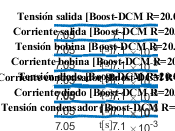

print(nombre,'-dpdf','-fillpage')

Buscamos maximos y minimos

posTinicio=find(out.t==inicio,1,"first");
posTfinal=find(out.t==(inicio+(3*T)),1,"first");
% Tensió salida
v_out=out.v_out(posTinicio:posTfinal);
v_ou_max=max(v_out)

v_ou_max = 11.5488

v_out_min=min(v_out)

v_out_min = 11.4190

V_o=((max(v_out)-min(v_out))/2)+min(v_out)

V_o = 11.4839

% Corriente salida
i_out=out.i_out(posTinicio:posTfinal);
i_out_max=max(i_out)

i_out_max = 0.5774

i_out_min=min(i_out)

i_out_min = 0.5710

% Tensió bobina
v_l=out.v_l(posTinicio:posTfinal);
v_l_max=max(v_l)

v_l_max = 4.9990

v_l_min=min(v_l)

v_l_min = -7.3493

% Corriente bobina
i_l=out.i_l(posTinicio:posTfinal);
i_l_max=max(i_l)

i_l_max = 3.5062

i_l_min=min(i_l)

i_l_min = -5.7815e-04

I_L=((max(i_l)-min(i_l))/2)+min(i_l)

I_L = 1.7528

% Tensión diodo
v_d=out.v_d(posTinicio:posTfinal);
v_d_max=max(v_d)

v_d_max = 0.8035

v_d_min=min(v_d)

v_d_min = -11.5113

% Corriente diodo
i_d=out.i_d(posTinicio:posTfinal);
i_d_max=max(i_d)

i_d_max = 3.5060

i_d_min=min(i_d)

i_d_min = -0.0105

% tension condensador
v_c=out.v_c(posTinicio:posTfinal);
v_c_max=max(v_c)

v_c_max = 11.5488

v_c_min=min(v_c)

v_c_min = 11.4190

% Corrienet condensador
i_c=out.i_c(posTinicio:posTfinal);
i_c_max=max(i_c)

i_c_max = 2.9351

i_c_min=min(i_c)

i_c_min = -0.5862

## Generar las graficas de VL y IL para la memoria

%graficas_memoria